clear all
close all
clc


## === Importing Experimental Data ===



Experimental_data_coil_2_stator = readmatrix("Coil_2_With_Stator_All_Currents.xlsx");

A10_Sensor_1to6 = Experimental_data_coil_2_stator(5:722, 12:17)';
A10_T_amb = Experimental_data_coil_2_stator(5:722, 18)';
A10_Sensor_ABC = Experimental_data_coil_2_stator(5:722, 19:21)';
A10_V_in = 1.26;                                % Inital voltage measured 
A10_V_fin = 1.42;                               % Final voltage measured
A10_Mean_Sensor = [];

% Creating a Mean value of all three sensors

for n = 1:length(A10_Sensor_ABC)
    
    A10_Mean_Sensor(end+1)= mean(A10_Sensor_ABC(:,n));

end



## === Importing Thermal Conductances ===


Conduction_Conductances = readmatrix("overview sheet AC.xlsx","Range","C27:C47")';
Conduction_Names = readcell("overview sheet AC.xlsx","Range","B27:B47")';

Convection_Conductances = readmatrix("overview sheet AC.xlsx","Range","N27:N42")';
Convection_Names = readcell("overview sheet AC.xlsx","Range","M27:M42")';

Capacitance_Values = readmatrix("overview sheet AC.xlsx","Range","C52:C67")';
Capacitance_Names = readcell("overview sheet AC.xlsx","Range","B52:B67")';


## === Chat GPT Automatically Allocating Variable Names and Values ===


for i = 1:length(Conduction_Names)
    name = Conduction_Names{i};
    value = Conduction_Conductances(i);
    eval([name ' = ' num2str(value) ';']);
end


for i = 1:length(Convection_Names)
    name = Convection_Names{i};
    value = Convection_Conductances(i);
    eval([name ' = ' num2str(value) ';']);
end


for i = 1:length(Capacitance_Names)
    name = Capacitance_Names{i};
    value = Capacitance_Values(i);
    eval([name ' = ' num2str(value) ';']);
end


## === Defining Parameters ===


N = 16;                                                                 % Number of nodes

T_ambient = mean(A10_T_amb);                                            % Ambient temperature in K taken from experimental data

G_conv = Convection_Conductances;                                                                                        % Manually inserting all nodes that have convection

C_vector = Capacitance_Values';                                         % Heat capacities per node (J/K)


## === Time Settings ===


t = linspace(0, 700, 100000);                                           % Time vector
dt = t(2) - t(1);                                                       % Time step


## === Power Input Setup ===


P_d = zeros(1,length(t));                                               % Initialising the power vector
[max_temp, t_peak] = max(A10_Mean_Sensor);                              % Determining the peak time and temperature from experimental data 
Power_increase_percent = A10_V_fin/A10_V_in;                            % Finding the percentual increase of power over the measured heating phase

time_step_factor = 1/dt;                                                % We introduce this facotr because t_peak is in seconds, but our time step in the t vector is much smaller to avoid instability
time_for_power_increase = round(t_peak*time_step_factor);               % we need an integer to replace values ina vector


## !!!!!!!!!! INPUT !!!!!!!!!!


I_DC = 10;                                                              % Amount of current used in testing
f = 1000;                                                                % AC frequncy in Hz


## !!!!!!!!!! INPUT !!!!!!!!!!



% Coil Parameters for power dissipation

resistivity_20C = 1.724*10^-8;                                          % in ohm*m resistivity at 20C
L_cu_tot = 5.54544130;                                                  % in m Total length of copper wire in the coil adjusted so that the initial resistance value matches the measured one of 82.19 mOhm
D_wire = 1.217*10^-3;                                                   % in m Wire diameter
A_cu = pi*(0.5*D_wire)^2;                                               % in m^2 Cross-sectional area of the wire from coil data

R_el = resistivity_20C*(L_cu_tot/A_cu);                                 % Calculating power dissipated from coil properties
P_d_initial = ((I_DC^2)*R_el)/2;


% Setting dissipated power as a linear increase matched with the measured results 

P_d(1:time_for_power_increase) = linspace(P_d_initial,P_d_initial*Power_increase_percent,time_for_power_increase);  




## === Calcuating Iron Losses ===


% experimentally determined vlaues from alvier

K_h = 1.0977375*10^-1;
K_e = 4.4280188*10^-5;
alpha = 1.75;

B_peak = 0;

P_Fe = zeros(N,length(t));

% Empirical Steinmetz equation

P_Fe(3:end,1:time_for_power_increase) = (K_h*f*B_peak^alpha) + (K_e*(f^2)*(B_peak)^2);

% Adding the iron losses to the general power vector

Power_Matrix = [P_d; P_d; P_Fe(3:end,:)];

## === Conductance Matrix Setup ===



G_matrix = zeros(N,N);                                                  % Initialize G matrix

% Define conduction connections (modify as needed)

connections = [1 3; 
    1 6; 
    1 7; 
    2 5; 
    2 6; 
    2 7; 
    3 4;
    4 6;
    4 7;
    5 4;
    6 15;
    7 8;
    7 9;
    8 9;
    8 10;
    9 10;
    10 11;
    11 12;
    12 16;
    7 13;
    10 14];                                                             % Chain of nodes

for k = 1:size(connections,1)
    i = connections(k,1);
    j = connections(k,2);
    G_matrix(i,j) = -Conduction_Conductances(k);
    G_matrix(j,i) = -Conduction_Conductances(k);
    G_matrix(i,i) = G_matrix(i,i) + Conduction_Conductances(k);
    G_matrix(j,j) = G_matrix(j,j) + Conduction_Conductances(k);         % We modify the j,j node because our connections matrix only counts each connection once
                                                                        % If we had [1 2] AND [2 1] in the connections matrix then this step would be unnecessary
                                              
end

% Add convection to diagonal 

for i = 1:N
    G_matrix(i,i) = G_matrix(i,i) + G_conv(i);                          % Adding the convection correspondant to each node 
end


## === Forward Euler Differencing ===



T = A10_Mean_Sensor(1) * ones(N, length(t));                             % Initialize all nodes to ambient

for n = 1:length(t)-1
    current_time = t(n);
    
    % Dynamic power vector

    P_vector_dynamic = Power_Matrix(:,n);

    % Compute net heat flow per node and update temperatures

    Q = P_vector_dynamic - G_matrix * T(:,n) + G_conv' .*T_ambient;
    T(:,n+1) = T(:,n) + (Q ./ C_vector) * dt;
end


## === Plotting ===

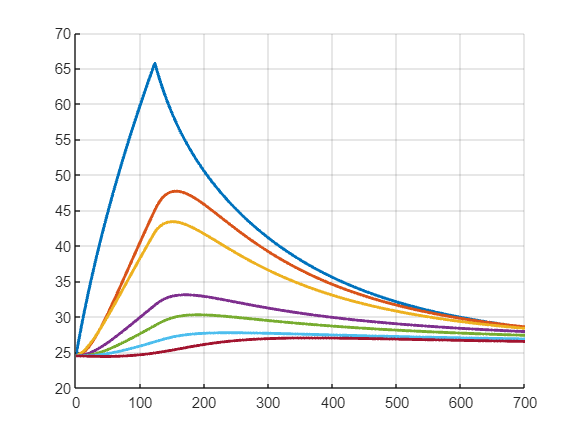

Simulated_sensors = [T(1,:);
T(15,:);
T(3,:);
T(7,:);
T(9,:);
T(10,:);
T(16,:)];

% Plotting only the nodes that also have sensors, to compare to experimental results

figure

hold on
grid on
plot(t, Simulated_sensors,Linewidth=2)


sensor_names = ["Simulated ABC mean"];

for i = 1:6
    sensor_names = [sensor_names, ("Simulated Sensor " + num2str(i))];
end



## === Plotting Experimental Data ===

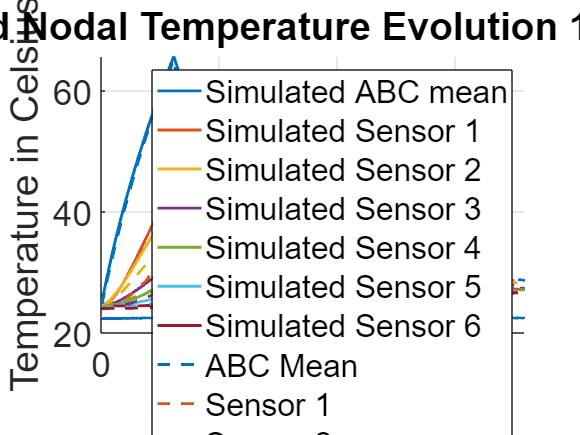

t_exp = linspace(1,length(A10_T_amb),length(A10_T_amb));


plot_legend = [sensor_names,"ABC Mean"];

plot(t_exp,A10_Mean_Sensor,linestyle = "--",Linewidth=2)

for n = 1:length(A10_Sensor_1to6(:,1))

    plot(t_exp,A10_Sensor_1to6(n,:),Linestyle = "--",Linewidth=2 )
    plot_legend = [plot_legend, "Sensor " + num2str(n)];

end


plot_legend = [plot_legend, "Ambient"];

plot(t_exp, A10_T_amb, Linewidth=2)
fontsize(24,"points")
xlabel('Time in Seconds')
ylabel('Temperature in Celsius')
title('Generalized Nodal Temperature Evolution 10A DC, Run 1')
legend(plot_legend)
grid on
hold off

## === Plotting the Error values ===

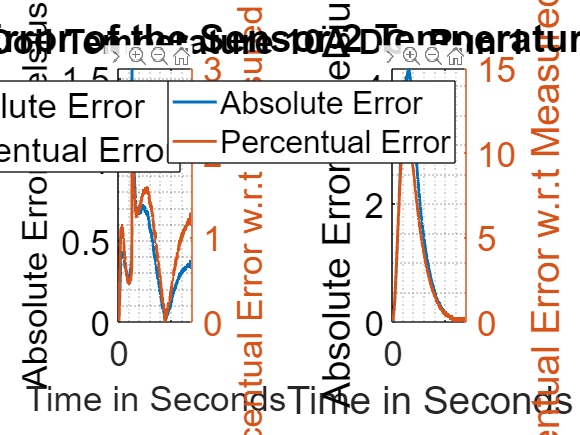

tiledlayout(1,2)
nexttile

% We do a few strange things here just to make the error vectors the same
% lengths. The timestep in the experimental and simulated model are very
% different, thats the reason for all this.

abserror = absolute_error(T(1,1:round(time_step_factor):end),A10_Mean_Sensor(1,1:700));
pererror = Percentual_error(T(1,1:round(time_step_factor):end),A10_Mean_Sensor(1,1:700));

plot(t_exp(1:700),abserror, LineWidth=2)
fontsize(24,"points")
title("Error of the Coil Temperature 10A DC, Run 1")
ylabel("Absolute Error in Celsius")
xlabel("Time in Seconds")
yyaxis right
plot(t_exp(1:700), pererror, LineWidth=2)
ylabel("Percentual Error w.r.t Measured Values")
legend('Absolute Error','Percentual Error')
grid minor



abserror = absolute_error(T(3,1:round(time_step_factor):end),A10_Sensor_1to6(2,1:700));
pererror = Percentual_error(T(3,1:round(time_step_factor):end),A10_Sensor_1to6(2,1:700));

nexttile
plot(t_exp(1:700),abserror, LineWidth=2)
fontsize(24,"points")
title("Error of the Sensor 2 Temperature 10A DC, Run 1")
ylabel("Absolute Error in Celsius")
xlabel("Time in Seconds")
yyaxis right
plot(t_exp(1:700), pererror, LineWidth=2)
ylabel("Percentual Error w.r.t Measured Values")
legend('Absolute Error','Percentual Error')
grid minor

**===  Error Determining Functions  ===**

function [abserror] = absolute_error(Modelled_Value, Measured_Value)

    abserror = abs(Modelled_Value-Measured_Value);

end


function[pererror] = Percentual_error(Modelled_Value, Measured_Value)

    pererror = (abs(Measured_Value-Modelled_Value))./Measured_Value;

    pererror = pererror.*100;                   % turning fraction into percent values
end
